# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
%Deci.Folder.Raw         = ['/Users/RobReinhart/Documents/Data/Behavioral'];              % Raw Data Folder Directory
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\AB2\' 'RawDataStim'];
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TrialDef, 2-PreProc, 3-Art Rej, 4-Analysis, 5-Plot
% Behavioral is 1 then 5
% Model is 1 then 4 then 5

% 1 is Trial definiton
% 2 is Preprocessing
% 3 is Artifact rejection
% 4 is Analysis
% 5 is Plotting

Deci.PCom               = false;  
%Deci.Folder.Version     = ['/Users/RobReinhart/Documents/Data/Processed_displace'];        % Output Folder Directory
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\AB2\' 'ProcessedDataStim'];

## 1. Trial Definitions

% Trial definition infomaton                                                                 % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.Static = [21 23];
Deci.DT.Displace.Markers = {[31 32] [51 52]};
Deci.DT.Displace.Duration =2;
Deci.DT.Displace.Num = 1;
%Displace will add a new marker of .Num*1000 + displaced trial marker

Deci.DT.Block.Markers   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = true;

## 5. Plotting

BlockTypes = @ceil;
CollapseBlocks = true;
CollapseSubjects = true;
CollapseTrials = true;
WriteExcel =  true;

Plot_singlet;

Deci.Run.Behavior = true; % for single and double
Deci.Run.Extra = true; % for model, double, triplet, 2std

## ** 6. Run**

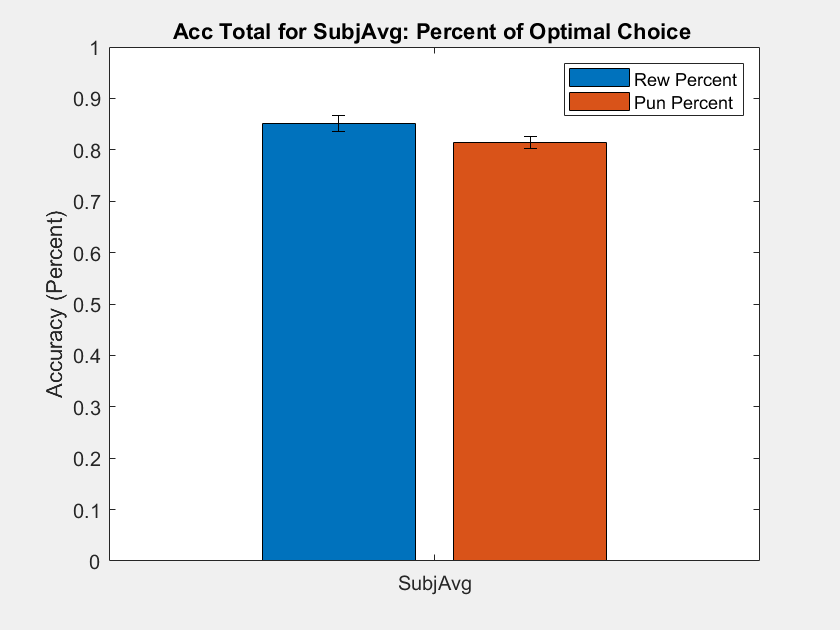

Acc Total for SubjAvg Percent of Optimal Choice 85.172% +- 1.5542
Acc Total for SubjAvg Percent of Optimal Choice 81.4029% +- 1.1648


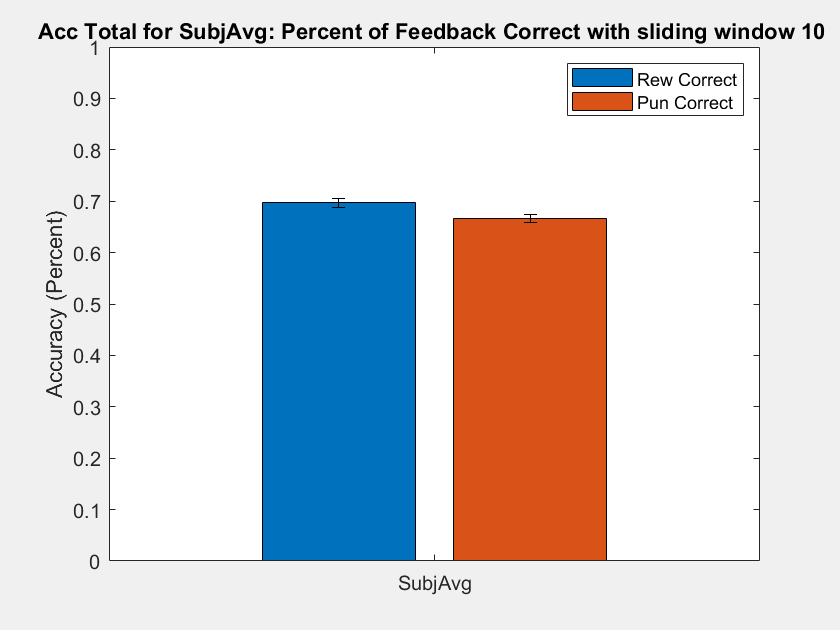

Acc Total for SubjAvg Percent of Feedback Correct with sliding window 10 69.6637% +- 0.95192
Acc Total for SubjAvg Percent of Feedback Correct with sliding window 10 66.6342% +- 0.82644


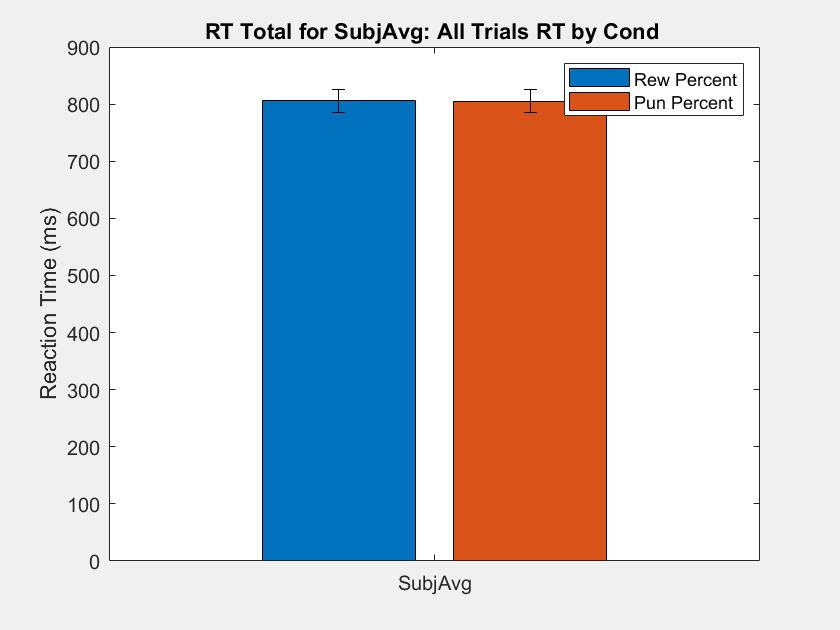

RT Total for SubjAvg Rew Percent 805.4748 +- 19.7581
RT Total for SubjAvg Pun Percent 805.1323 +- 19.6723


Unrecognized method, property, or field 'Children' for class 'matlab.graphics.GraphicsPlaceholder'.

Error in Plottor_Behv (line 586)
        d(lim).Children(end).YLim = minmax(cell2mat(arrayfun(@(c) [c.Children(end).YLim],d(:)','UniformOutput',false)));

Error in Plottor (line 59)
    Plottor_Behv(Deci);

Error in 

Deci_Backend(Deci);